# MATLAB Analysis:

## Load Data:

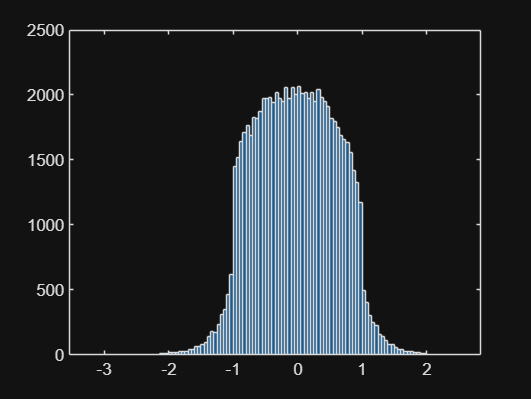

load( 'weightsAndBiases.mat', 'W1', 'b1', 'W2', 'b2' ) ;
images = loadMNISTImages( 't10k-images' ) ;
labels = loadMNISTLabels( 't10k-labels' )' ;

histogram(W1)

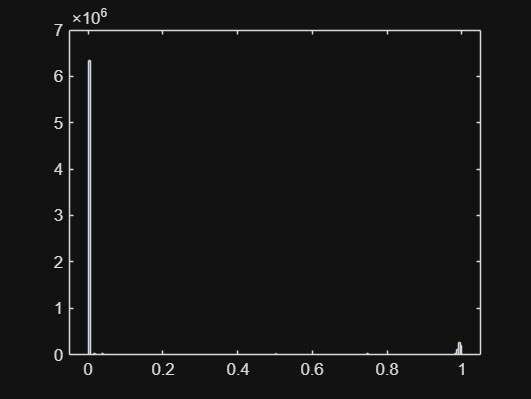

histogram(images)

## Part 1: Finding minimal Bx and Bw

%{
Min_acc = 97.4300 - 0.1;
for w = 2:8
    for wf = 0:w
        for x = 1:4
           for xf = 0:x
               %% LAYER 1
               % quantization on weights and images
               W1_Q = fi(W1,1,w,wf);
               X1_Q = fi(images,0,x,xf);
               z1 = W1_Q.data * X1_Q.data + b1;
               a1 = max(0, z1);

               %% LAYER 2
               z2 = W2 * a1 + b2 ;
               [ ~, guesses ] = max( z2, [], 1 ) ; guesses = guesses - 1 ;
               
               %% Get Accuracy
               NumMatches = sum( labels == guesses ) ;
               Acc = NumMatches / numel( labels ) * 100 ;
               if Acc > Min_acc
                   fprintf('For (w=%d, wf=%d)  (x=%d, xf=%d)  -> Accuracy = %.4f\n',w, wf, x, xf, Acc);
               end
           end
        end
    end
end
fprintf('END')
%}

### Results:

`For (w=5, wf=3)  (x=4, xf=4)  -> Accuracy = 97.3600`

`For (w=6, wf=3)  (x=2, xf=2)  -> Accuracy = 97.3900`

`For (w=6, wf=3)  (x=3, xf=3)  -> Accuracy = 97.3400`

`For (w=6, wf=4)  (x=4, xf=4)  -> Accuracy = 97.3700`

`For (w=7, wf=3)  (x=2, xf=2)  -> Accuracy = 97.3900`

`For (w=7, wf=3)  (x=3, xf=3)  -> Accuracy = 97.3400`

`For (w=7, wf=4)  (x=3, xf=3)  -> Accuracy = 97.3700`

`For (w=7, wf=4)  (x=4, xf=3)  -> Accuracy = 97.3400`

`For (w=7, wf=4)  (x=4, xf=4)  -> Accuracy = 97.4000`

`For (w=7, wf=5)  (x=3, xf=3)  -> Accuracy = 97.3500`

`For (w=7, wf=5)  (x=4, xf=4)  -> Accuracy = 97.3900`

`For (w=8, wf=3)  (x=2, xf=2)  -> Accuracy = 97.3900`

`For (w=8, wf=3)  (x=3, xf=3)  -> Accuracy = 97.3400`

`For (w=8, wf=4)  (x=3, xf=3)  -> Accuracy = 97.3700`

`For (w=8, wf=4)  (x=4, xf=3)  -> Accuracy = 97.3400`

`For (w=8, wf=4)  (x=4, xf=4)  -> Accuracy = 97.4000`

`For (w=8, wf=5)  (x=2, xf=2)  -> Accuracy = 97.3500`

`For (w=8, wf=5)  (x=3, xf=3)  -> Accuracy = 97.3700`

`For (w=8, wf=5)  (x=4, xf=4)  -> Accuracy = 97.4400`

`For (w=8, wf=6)  (x=3, xf=3)  -> Accuracy = 97.3500`

`For (w=8, wf=6)  (x=4, xf=4)  -> Accuracy = 97.4200`

## Part 1 - Conclusion:

Based on the above results - choosing Bx, Bw as (6,2) and (2,2) is the best choice.

%Fixing values
w = 6;
wf = 2;
x= 2;
xf = 2;

## Part 2: Finding minimal Badc and Clipping point:

Min_acc = 97.4300 - 0.75 ;
%% LAYER 1
% quantization on weights and images
W1_Q = fi(W1,1,w,wf);
X1_Q = fi(images,0,x,xf);

%% Weights- Pad to 1024 columns (100*784)
W_Q = [W1_Q fi(zeros(size(W1_Q,1), 1024 - size(W1_Q,2)), 1, w, wf)];
% Split into 8 matrices (10000 x 128 each)
W_split = mat2cell(W_Q, size(W_Q,1), repmat(128,1,8));

%%Input- Pad rows (784 → 1024)(784*10000)
X_Q = [X1_Q; fi(zeros(1024 - size(X1_Q,1), size(X1_Q,2)), 0, x, xf)];
% Split into 8 matrices (128 x 10000 each)
X_split = mat2cell(X_Q, repmat(128,1,8), size(X_Q,2));

%% MAC of 128 
MAC = cell(1, 8); 
allMACvalues = [];
for a = 1:8
    MAC{a} = W_split{a}.data * X_split{a}.data; 
    allMACvalues = [allMACvalues; MAC{a}(:)];
end

### Find the best possible q:


for q = 2:8 
    MAC_Q = cell(1,8); 
    finalMAC = zeros(100, 10000);     
    for a = 1:8 
        MAC_Q{a} = fi(MAC{a}, 1, q, 0);
        finalMAC = finalMAC + MAC_Q{a}.data; 
    end 
    finalMAC = finalMAC + b1; 
    a1 = max(0, finalMAC);
    
    %% LAYER 2
    z2 = W2 * a1 + b2 ;
    [ ~, guesses ] = max( z2, [], 1 ) ; guesses = guesses - 1 ;

    %% Get Accuracy
    NumMatches = sum( labels == guesses ) ;
    Acc = NumMatches / numel( labels ) * 100;
    if Acc > Min_acc
        fprintf('For (q=%d)  -> Accuracy = %.4f\n',q,Acc);
    end
end

For (q=5)  -> Accuracy = 96.9700
For (q=6)  -> Accuracy = 97.0700
For (q=7)  -> Accuracy = 97.0700
For (q=8)  -> Accuracy = 97.0700


fprintf('END');

END

### Results:

`For (q=5)  -> Accuracy = 96.9700`

`For (q=6)  -> Accuracy = 97.0700`

`For (q=7)  -> Accuracy = 97.0700`

`For (q=8)  -> Accuracy = 97.0700`

### `Conclusion:`

`Choosing q = 5.`

### `Finding the optimal clipping point:`

q = 5;
best_acc = 0;
best_alpha = 0;
p = linspace(99, 99.99, 100);
alpha_vals = prctile(abs(allMACvalues), p);
for alpha = alpha_vals
    MAC_clipped = cell(1,8);
    MAC_Q = cell(1,8); 
    finalMAC = zeros(100, 10000); 
    for a = 1:8 
        % --- CLIPPING ---
        MAC_clipped{a} = min(max(MAC{a}, -alpha), alpha);
        % --- QUANTIZATION ---
        MAC_Q{a} = fi(MAC_clipped{a}, 1, q, 0);
        finalMAC = finalMAC + MAC_Q{a}.data; 
    end 
    finalMAC = finalMAC + b1; 
    a1 = max(0, finalMAC);
    
    %% LAYER 2
    z2 = W2 * a1 + b2 ;
    [ ~, guesses ] = max( z2, [], 1 ) ; guesses = guesses - 1 ;
    
    %% Get Accuracy
    NumMatches = sum( labels == guesses ) ;
    Acc = NumMatches / numel( labels ) * 100;
    if Acc > best_acc
        best_acc = Acc;
        best_alpha = alpha;
        fprintf('New best accuracy: %.4f with alpha: %.4f\n', best_acc, best_alpha);
    end
end

New best accuracy: 96.7500 with alpha: 11.2500
New best accuracy: 96.8500 with alpha: 11.5000
New best accuracy: 96.9200 with alpha: 12.5000
New best accuracy: 96.9700 with alpha: 13.5000


fprintf("END");

END

### Results:

`New best accuracy: 96.7500 with alpha: 11.2500`

`New best accuracy: 96.8500 with alpha: 11.5000`

`New best accuracy: 96.9200 with alpha: 12.5000`

`New best accuracy: 96.9700 with alpha: 13.5000`

### Conclusion:

Choosing clipping point as = 13.5, it gives an accuracy of 96.97%.

max_MAC = max(allMACvalues)

max_MAC = 35.8750

min_MAC = min(allMACvalues)

min_MAC = -32.6250

## MATLAB Analysis conclusion:

**Final Quantization & Clipping Results (MNIST Inference)**

- **Input Quantization (Bx):** (x = 2, xf = 2) 

- **Weight Quantization (Bw):** (w = 6, wf = 3) 

- **Achieved Accuracy (Bx, Bw):** **97.39%**

- **MAC Quantization (q):** 5 bits 

- **Achieved Accuracy after MAC Quantization:** **96.97%**

- **Optimal Clipping Threshold (α):** 13.5 

- **Final Accuracy (with clipping + quantization):** **96.97%**